# **Week 6: cells and structures**

**(live script created by E. Mika Diamanti on July 3rd 2025; contact: emdiamanti@princeton edu)**

This live script introduces cells and structure arrays, these are datatypes that are widely used for storing and analyzing (heterogeneous) data.

Topics covered are:

- storing data in cell and structure arrays

- access data in cell and structure arrays

- applying functions to the contents of cell and structure arrays

## **Intro**

During the intro in matalb you learnt about Matlab *arrays. *These can be of any size.

a) its elements have to be the same data type

b) they are rectangular, i.e. every column has the same number of rows.

But! this is not what our data always look like. For instance you may collect data of various datatypes, eg. mouse name, session date, correct versus error trials, or behavioral variables such as running speed. See an actual example by loading teto6s_14_20211102_Behavior.mat

One way around it, is to save each type of data in a separate variable - too messy!

*Need an array that can store different types and sizes of data! ****container variables, i.e. arrays that contain other arrays. ***

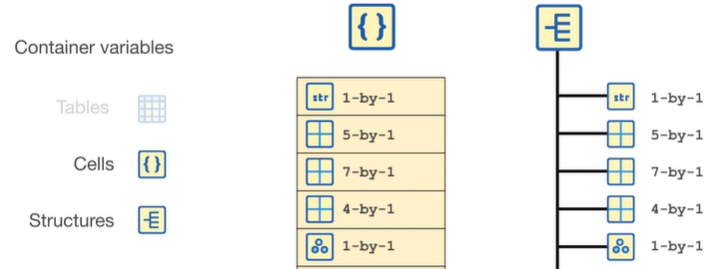

These are tables (not covered here), cells and structures. 

*Cells and structures allow completely heterogeneous data, but this flexibility comes with some complexity..*

## Cell arrays

Think of a cell array as a dresser. You can put in each drawer (cell) whatever you want. 

Cell arrays are rectangular, but other than that there is no other assumed structure.

### Create cell arrays

To create a cell array, use the curly brackets. Use same convention for rows (',') and columns (';') as for arrays.

Data = {'M031', '20240305'; 28, true};

% mouse name, DoB;
% weight (gr), inExperiments     

 Limitation: does not store metadata

####  Example: elements of cell arrays can be different sizes 

load('speed_first3Trials.mat')

% create a horizontal cell array, C_hor,  in the order trial 1,2,3


% create a vertical cell array, C_ver,  in the order trial 1,2,3


% and then create a separate array with the description of C_hor, called
% description


Cell arrays can also be concatenated in the same way as numeric arrays (using the square brackets) -make sure sizes are compatible!-

% create a cell array, called C, that combines the descriptions in the first row with
% C_hor in the 2nd row

%try with C_ver?

Cell arrays can contain even other cell arrays as elements

% create a cell array that contains in the first element the definition 'my cell', 
% in the second element it contains the description and 
% in the third element the actual C_hor.


### Access data in cell array

- To access a subset of cells in cell array, use parentheses '()'

- To access the contents *inside* the cells, use curly brackets '{}' -Remember! curly for content-

% In Data, extract the cell in the 2nd row and first column. What is
% the data type of the extracted variable?


% In Data, extract the information of whether the animal is in experiments
% or not. What is the data type of this variable?


### Remove or add data in cell array

To remove an element from a cell array assign an empty array '[]'

%remove all elements in the second row of Data


You can add data by updating *the content* of an additional element. This will automatically increase the cell's size.

% add the string 'male' in the 3rd column of the new cell


## Structure arrays

These are arrays of structures. With structures you can name the types of information stored using 'field names'.

####  Example (from my actual data): all behavioral data acquired in one session are stored in structure arrays

Note: the dimensionality of the structure (array) is *not *determined by the number of fields ('columns')

load('teto6s_14_20211102_Behavior.mat')
%numel(trialStats)


- each row in the structure array is a structure and corresponds to a single trial.

- note the different data types and sizes across elements!

### Create structures

To create a structure Struct with fieldName Field and assigned variable var, use **the dot notation**: 

Struct.Field = var. 

% create a stucture called Subjects with field name MouseName and assign the
% value 'Minnie' to that field

% use dot notation to add a second field to the structure, for example add
% the field 'DoB' with value '19281118'

%size(Subjects)

Instead of the dot notation, one may use the struct(), defined as: 

myStruct = struct(field1, value1, ..., fieldN, valueN)

%Use the struct function to create another structure Subjects2 for Mickey
%with same DoB as above


### Add elements to a structure array

% add a second element in the structure called Subjects, by adding the name 'Mickey' to the field 'MouseName'


% note matlab automatically adds an empty double array to the undefined
% field 'DoB' for Mickey


You now have a structure array of size 2.

%What happens if you try defining a scalar structure with the same name and
%a new value? for example:

%Subjects.MouseName = 'Emma';


### Extract an element from a structure array

Use numerical indexing with parentheses (like in numerical arrays). What data type is the output?

% From the trialStats, extract the 10th trial and assigne it to a
% variable called tenthTrial


### Extract data from a structure

Use same dot notation as when defining it

% from the tenthTrial, extract the content of the field 'cue_pos_right'


Combine array indexing with dot indexing, to extract a specific field from a specific element in the structure array

% from the trialStats, extract the trial's outcome (correct or error) from the 150th trial

% was that choice correct?


## Index into multiple elements of a cell or structure array

That's a littlebit trickier than extracting multiple elements from matrices, because of the heterogeneity of the contents. 

But to be able to analyze the data, we do need to extract and combine all of the data from each field! 

%try extracting the contents of the first row from the cell array Data using the
%same indexing as if it was a numeric array

%similarly, use same notation to extract the mouse's choice (went_right or went_left) from the
%first 5 trials of the trialStats


% now run this code to see the output of a comma-separated list
5,8,'Mika',true

So these outputs are like the outputs of a comma-separated list, that is the output of  multiple, separate commands.

What happens if you assign these multiple outputs to a variable?

% write code here


  So how do we group the multiple outputs together?

% try {} or []

The answer is (horizontal) concatenation!

- if all contents of the cells are scalar , you can concatenate with '[]' (as with numeric arrays). 

CellOfScalars{1,1} = 10; CellOfScalars{1,2} = 20; CellOfScalars{2,1} = 30; CellOfScalars{2,2} = 40; 

CellOfScalars{:}

% concatenate horizontally

% what if you want to concatenate vertically, resulting into a column
% vector (rather than row vector?)


% which other field in the trialStats can be concatenated with []? (there's multiple, pick 2)

- if the data are of different type or size, you need '{}', resulting into another cell.

% try concatenating trialStats.position_y with {}

%try concatenating trialStats.position_y with []

% try concatenating trialStats.cue_pos_right with {}

% try concatenating trialStats.cue_pos_right with []


#### Practice 1

- from trialStats extract the field position_y between the 100th and the 106th trial. Assign it to a variable named 'pos_y'

- from trialStats extract the field position_theta fbetween the 100th and the 106th trial. Assign it to a variable named 'theta'

- For each trial, plot pos_y against theta. Use sublot to create a 3 x 2 subplots, one for each trial. Use a for loop to generate one plot per trial.

#### Practice 2

Concatenate the speed trace ('run_speed_instant') across the first 10 trials and plot it

## Operate on all elements of a stucture or cell array

Many Matlab functions are *vectorized *(see next week!). That means that Matlab inbuilt functions are applied element-wise on numeric arrays. For eg,

A = [0 pi/3, pi/2, 3/4*pi]; % A is a row vector
sin(A) % the Matlab sin() is applied on all elements of A (no need for a for loop)

That is not the case for non homogeneous datatypes!

- One way to apply a function on each element of a cell or structure array is ...(?)

A second (often faster) way is to use a special function, the cellfun() for cell arrays, and the arrayfun() for structure arrays. 

Example: find the length of each element in theta

% that won't work:
length(theta) % this will return the length of the cell structure (composed of 6 cells)

cellfun() (or arrayfun()) take two inputs: 

1. the function to be applied

2. the cell (or structure) array to apply the function to

- to specify the operation use a 'function handle' (@): we use function handles to pass a function to another function 

%calculate the length of all elements in theta
%lengthOfElements = cellfun

For structure arrays now we also need to specify the field we're applying the function to. The field needs to be specified as input to the function. (basically we are passing an **anonymous function***)

%calculate the length of all elements in trialStats.position_theta


By default cellfun() and arrayfun() expect a scalar as output for each element. If the output is a non-scalar then you need to set the flag 'UniformOutput' to false

%calculate the size of all elements in trialStats.position_theta

Using cellfun() (or arrayfun()) can be really handy for performing *multiple* operations with one line of code.

%estimate the smallest length in theta

What does the output look like if a cell has multiple rows and columns?

% use cellfun to estimate the length of all elements in Data

### *Anonymous functions

To create an anonymous function, use the `@` symbol, specify the inputs in parentheses, and then define the expression.

for example, create an anonymous function called maxDiff that estimates the maximum difference between two consecutive values of theta

% maxDiff

- Apply anonymous functions on cell arrays

Appy maxDiff to the first element of the cell array called theta

Apply maxDiff to all elements of theta

The anonymous function does not need to be written in a separate line. It can be passed straight into cellfun()

- Apply anonymous functions on structure arrays

Anonymous functions can be used to extract a specific field from a structure array

%create a function handle called isCorrect to extract the field is_correct from trialStats

Apply the anonymous function to the first element of trialStats

Apply the anonymous function to all elements of trialStats

Find the maximum speed on each trial of trialStats

(tricky) Find the maximum speed across the whole session by first pooling out all speed values across all trials and then taking the max

% let's do it step by step
% first extract the field run_speed_instant from trialStats

% second..

% third, 

% now do all the above in one line


cell2mat() is one example Matlab function that converts between datatypes, from cells into homogeneous arrays. The inverse operation is called mat2cell().

'struct2mat' does not exist/ does not make sense 